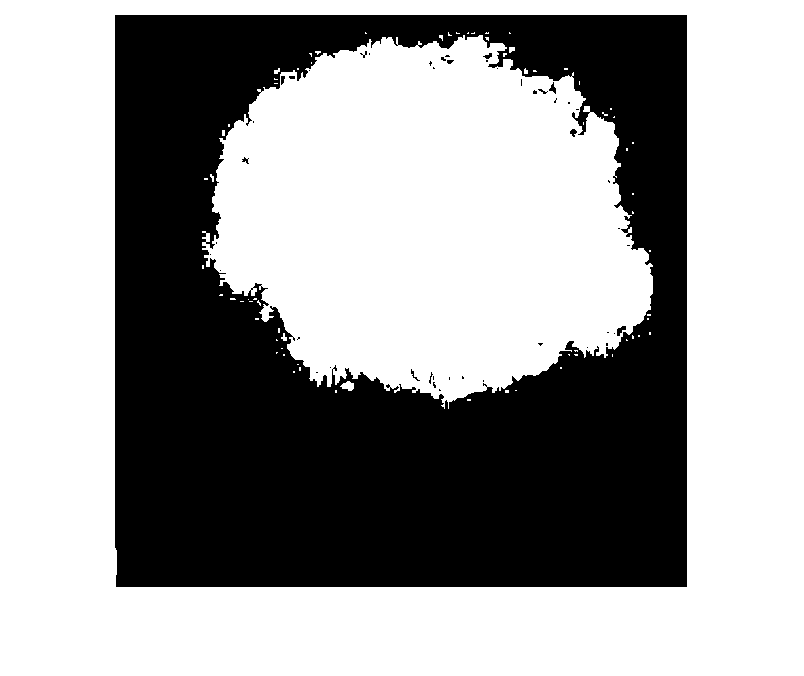

clear all;
clc;

leftImage = double(imread('tiger.png'));
rightImage = double(imread('great.png'));

iternum = 3;

if (size(leftImage) ~= size(rightImage))
    error('Input images are not the same size!')
end

% 预处理，使图片height,width为偶数
[rows, cols, channels] = size(leftImage);

% mask gaussian
mask = double(imread("mask.png"));
mask = im2gray(mask);
mask = imbinarize(mask);
imshow(mask);

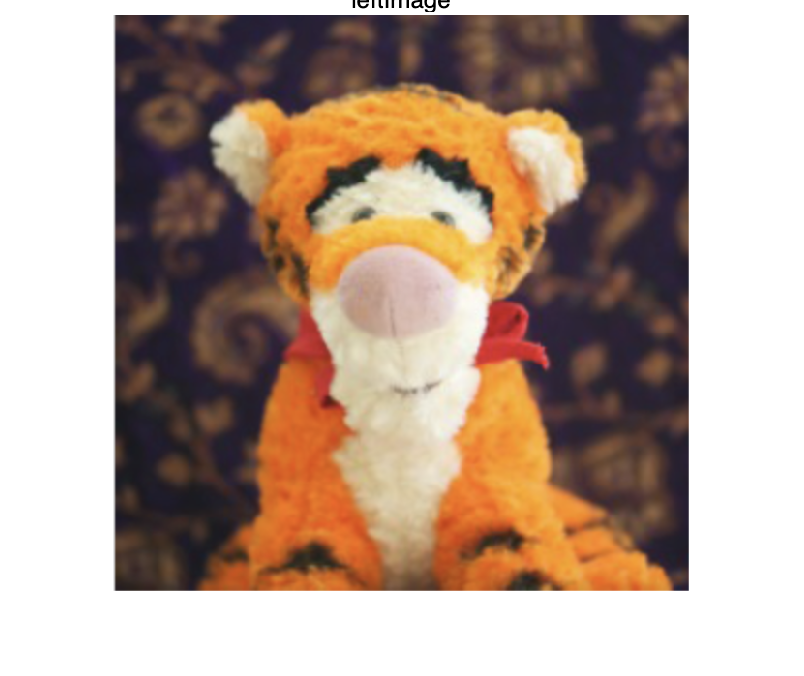

mask_pyramid = GaussianPyramid(mask, iternum);


% leftImage pyramid and rightImage pyramid
left_pyramid = LaplacianPyramid(leftImage, iternum);
right_pyramid = LaplacianPyramid(rightImage, iternum);

% TODO: get blend laplacian pyramid
blend_pyramid = cell(iternum, 1);
for i = 1:iternum
    blend_pyramid{i} = left_pyramid{i} .* mask_pyramid{i} + right_pyramid{i} .* (1 - mask_pyramid{i});
end

% reconstruct the blend image
blendImage = LaplacianReconstruct(blend_pyramid);
imwrite(uint8(blendImage), 'region_blendImage.png');

figure;
imshow(uint8(leftImage));
title('leftImage');

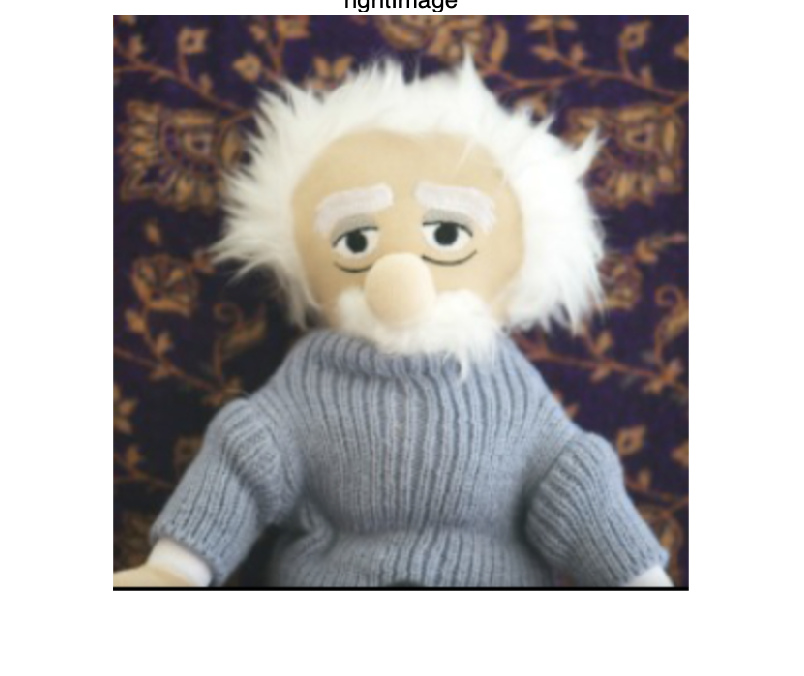

figure;
imshow(uint8(rightImage));
title('rightImage');

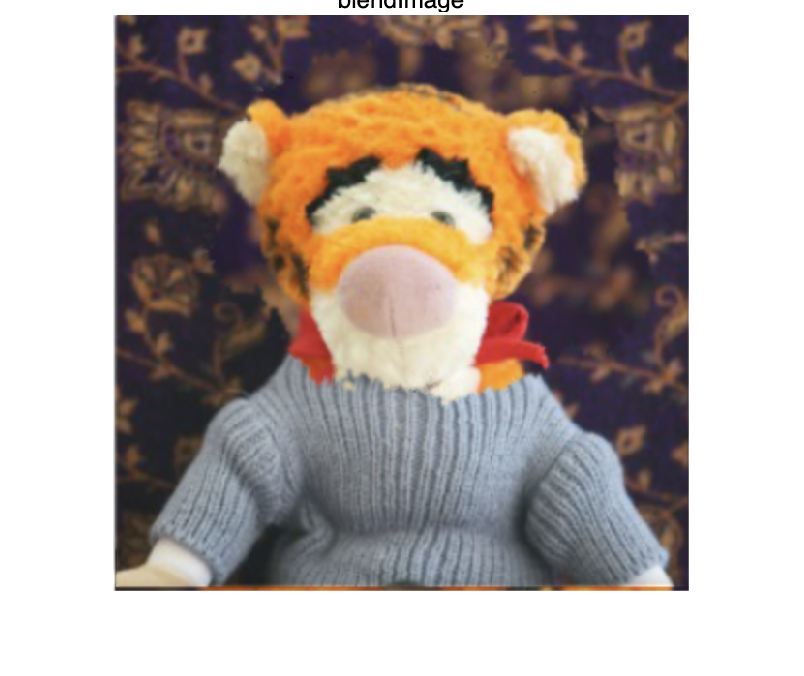

figure;
imshow('region_blendImage.png');
title('blendImage');